%========================================

% {5.1} Single Dev Model

%========================================


%========================================
% {5.1.1} Single Dev Model for Response
%========================================

clc
clear
addpath("D:\matlab23a\bin\20240728-RC代码整理\public_func")
load("single_device_model_data.mat")

addpath("D:\matlab23a\bin\small_func")

gt_path = ['D:\matlab23a\bin\20240728-RC代码整理\' ...
    '20240818\wave_classification_gt.txt'];

Label = readmatrix(gt_path)';

Input = readmatrix("wave_classification_laser.txt");
Input_ex = 37 + Input*6;

ML = 4;
N = 14;
time_step = 0.2;

mask = zeros(14,ML);
tic
for i = 1:14
t = dec2bin(i,4)';
t = string(t);
mask(i,:) = str2double(t)';
end
mask(mask == 0) = -1;
mask = [1 1 1 1;
        -1 -1 -1 -1];

input_num = size(Input,1);
tao_range = 0.1:0.1:0.7;
data_size = size(tao_range,2)*2;
var_range = 0.001:0.001:0.01;

NARMSE_var = zeros(size(var_range));
ind_var = 1;

for var = var_range
    curve_v_all = zeros(data_size,input_num*ML);
    ind = 1;
    disp(['====Var:',num2str(var),'===='])
    for tao = tao_range
        c_v_last = zeros(2,1);
        curve_v = [];
        mask_temp_last = [];
        % disp(['====tao:',num2str(tao),'===='])
        for i = 1:input_num
            for j = 1:ML
                mask_temp = mask(:,j);
                [a,b] = get_ab(Input_ex(i),mask_temp, ...
                    p_fitresult_a,p_fitresult_b,n_fitresult_a,n_fitresult_b, ...
                    nd_b_mean,pd_b_mean);
                if ~isempty(mask_temp_last)
                    a_zeros_index = a == 0;
                    change_polarity = (mask_temp - mask_temp_last)/2;
                    change_index = change_polarity ~= 0;
                    a(change_index&a_zeros_index) = change_polarity(change_index&a_zeros_index)/0.3;
                end
                a = var*randn(size(a)) + a;
                b = var*randn(size(b)) + b;
                result_fake = (a - c_v_last).*(1-exp(-time_step./b))+c_v_last;
                curve_v(:,ML*(i-1)+j) = result_fake;
                c_v_last = curve_v(:,ML*(i-1)+j);
                mask_temp_last = mask_temp;
            end
        end
        % disp(['====tao:',num2str(tao),'Done...===='])
        curve_v_all(ind:ind+1,:) = curve_v;
        ind = ind+2;
    end



    mask_num = data_size;
    step = 1000;
    Label_train = Label(1:step);
    Label_test = Label(step+1:end);

    jj_range = -20:1:20;
    fac_range = 1:20;
    NR = zeros(size(fac_range,2),size(jj_range,2));
    rowmin = min(curve_v_all,[],2);
    rowmax = max(curve_v_all,[],2);

    NR = search_para(fac_range,jj_range,step,ML,curve_v_all,rowmin,rowmax,Label);
    [fac,jj] = plot_para(NR,fac_range,jj_range,curve_v_all, rowmin,rowmax,ML,step,Label,0);

    jj_range = jj-2:0.1:jj+2;
    fac_range = fac-2:0.1:fac+2;

    NR = search_para(fac_range,jj_range,step,ML,curve_v_all,rowmin,rowmax,Label);
    [~,~,NRMSE] = plot_para(NR,fac_range,jj_range,curve_v_all,rowmin,rowmax,ML,step,Label,0);
    NARMSE_var(ind_var) = NRMSE;
    disp(['====Var:',num2str(var),'Done...===='])
    ind_var = ind_var + 1;
end

====Var:0.001====


====Var:0.001Done...====


====Var:0.002====


====Var:0.002Done...====


====Var:0.003====


====Var:0.003Done...====


====Var:0.004====


====Var:0.004Done...====


====Var:0.005====


====Var:0.005Done...====


====Var:0.006====


====Var:0.006Done...====


====Var:0.007====


====Var:0.007Done...====


====Var:0.008====


====Var:0.008Done...====


====Var:0.009====


====Var:0.009Done...====


====Var:0.01====


====Var:0.01Done...====


toc

历时 207.486487 秒。


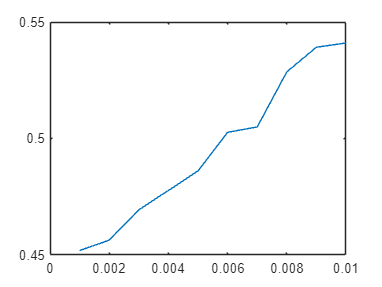

figure
plot(var_range,NARMSE_var)

save('NRMSE vs var no mask','NARMSE_var','var_range')

%========================================

% {5.1} Single Dev Model

%========================================


%========================================
% {5.1.1} Single Dev Model for Response
%========================================

clc
clear
addpath("D:\matlab23a\bin\20240728-RC代码整理\public_func")
load("single_device_model_data.mat")

Input = readmatrix("wave_classification_laser.txt");
Input_ex = 37 + Input*6;

ML = 4;
N = 14;
time_step = 0.2;

mask = zeros(14,ML);

for i = 1:14
t = dec2bin(i,4)';
t = string(t);
mask(i,:) = str2double(t)';
end
mask(mask == 0) = -1;

input_num = size(Input,1);


var_range = 0.001:0.001:0.01;

NARMSE_var = zeros(size(var_range));
ind_var = 1;
tic
for var = var_range

c_v_last = zeros(N,1);
curve_v = [];
mask_temp_last = [];

for i = 1:input_num
    for j = 1:ML
        mask_temp = mask(:,j);
        [a,b] = get_ab(Input_ex(i),mask_temp, ...
    p_fitresult_a,p_fitresult_b,n_fitresult_a,n_fitresult_b, ...
    nd_b_mean,pd_b_mean);
        if ~isempty(mask_temp_last)
            a_zeros_index = a == 0;
            change_polarity = (mask_temp - mask_temp_last)/2;
            change_index = change_polarity ~= 0;
            a(change_index&a_zeros_index) = change_polarity(change_index&a_zeros_index)/0.3;
        end
        a = var*randn(size(a)) + a;
        b = var*randn(size(b)) + b;
        result_fake = (a - c_v_last).*(1-exp(-time_step./b))+c_v_last;
        curve_v(:,ML*(i-1)+j) = result_fake;
        c_v_last = curve_v(:,ML*(i-1)+j);
        mask_temp_last = mask_temp;
    end
end


gt_path = 'D:\matlab23a\bin\20240728-RC代码整理\20240818\wave_classification_gt.txt';
mask_num = N;
Label = readmatrix(gt_path)';

step = 1000;
Label_train = Label(1:step);
Label_test = Label(step+1:end);
ML = 4;


jj_range = -20:1:20;
fac_range = 1:20;
NR = zeros(size(fac_range,2),size(jj_range,2));
rowmin = min(curve_v,[],2);
rowmax = max(curve_v,[],2);

NR = search_para(fac_range,jj_range,step,ML,curve_v,rowmin,rowmax,Label);
[fac,jj] = plot_para(NR,fac_range,jj_range,curve_v, rowmin,rowmax,ML,step,Label,0);

jj_range = jj-2:0.1:jj+2;
fac_range = fac-2:0.1:fac+2;

NR = search_para(fac_range,jj_range,step,ML,curve_v,rowmin,rowmax,Label);
[fac,jj,NRMSE] = plot_para(NR,fac_range,jj_range,curve_v,rowmin,rowmax,ML,step,Label,0);
NARMSE_var(ind_var) = NRMSE;
disp(['====Var:',num2str(var),'Done...===='])
ind_var = ind_var + 1;
end

====Var:0.001Done...====
====Var:0.002Done...====
====Var:0.003Done...====
====Var:0.004Done...====
====Var:0.005Done...====
====Var:0.006Done...====
====Var:0.007Done...====
====Var:0.008Done...====
====Var:0.009Done...====
====Var:0.01Done...====


toc

历时 136.741019 秒。


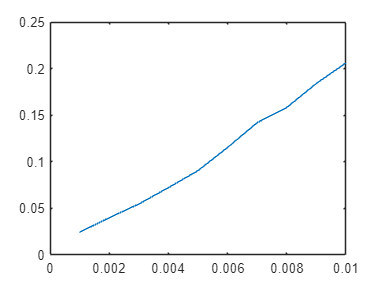

figure
plot(var_range,NARMSE_var)

save('NRMSE vs var with mask','NARMSE_var','var_range')

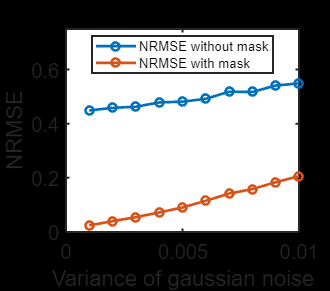

load("NRMSE vs var no mask.mat")
NARMSE_var_no_mask = NARMSE_var;
load("NRMSE vs var with mask.mat")
NARMSE_var_with_mask = NARMSE_var;

figure

plot(var_range,NARMSE_var_no_mask,'LineWidth',2,'Marker','o','MarkerSize',6)
hold on
plot(var_range,NARMSE_var_with_mask,'LineWidth',2,'Marker','o','MarkerSize',6)
legend('NRMSE without mask','NRMSE with mask', ...
    'Location','best', ...
    'fontsize',10)
figure_setting('NRMSE vs Variance',15,1.5,15)
grid off
xlabel('Variance of gaussian noise')
ylabel('NRMSE')
sc_size = get(0,'screensize');
set(gcf,'Position',[sc_size(1) sc_size(2) sc_size(3)*0.172 sc_size(4)*0.269 ...
    ])
ylim([0 0.75])
set(gca,'TickLength',[0.015 0.3])

% title('NRMSE vs Variance','FontSize',10,'FontName','Arial')
set(gcf,'color','none','InvertHardcopy','off');
print(gcf,'bar2 NRMSE vs Mask length','-dmeta','-r600')

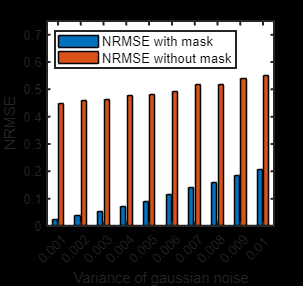


figure
bar([NARMSE_var_with_mask',NARMSE_var_no_mask'])
xticklabels(mat2cell(var_range,1,10))
legend('NRMSE with mask','NRMSE without mask', ...
    'Location','northwest', ...
    'fontsize',10)
ylabel('NRMSE')
xlabel('Variance of gaussian noise')
% figure_setting('',15,1.5,15)
set(gca,'linewidth',1.5)
set (gca,'FontName','Arial','fontsize',10);

grid off
sc_size = get(0,'screensize');
set(gcf,'Position',[sc_size(1) sc_size(2) sc_size(3)*0.158 sc_size(4)*0.265 ...
    ])
ylim([0 0.75])
set(gca,'TickLength',[0.015 0.3])

% title('NRMSE vs Variance','FontSize',10,'FontName','Arial')
set(gcf,'color','none','InvertHardcopy','off');
print(gcf,'bar NRMSE vs Mask length','-dmeta','-r600')

%========================================

% {5.1} Single Dev Model

%========================================


%========================================
% {5.1.1} Single Dev Model for Response
%========================================

clc
clear
addpath("D:\matlab23a\bin\20240728-RC代码整理\public_func")
load("single_device_model_data.mat")

addpath("D:\matlab23a\bin\small_func")

Input = readmatrix("20241219_wire_less_laser.txt");
Input_ex = 37 + Input*6;
gt_path = '20241219_wire_less_laser_gt.txt';
Label = readmatrix(gt_path);

ML = 4;
N = 14;
time_step = 0.2;

mask = zeros(14,ML);
tic
for i = 1:14
t = dec2bin(i,4)';
t = string(t);
mask(i,:) = str2double(t)';
end
mask(mask == 0) = -1;
mask = [1 1 1 1;
        -1 -1 -1 -1];

input_num = size(Input,1);
tao_range = 0.1:0.1:0.7;
data_size = size(tao_range,2)*2;
var_range = 0.001:0.001:0.01;

NARMSE_var_nomask = zeros(size(var_range));
ind_var = 1;

for var = var_range
    curve_v_all = zeros(data_size,input_num*ML);
    ind = 1;
    disp(['====Var:',num2str(var),'===='])
    for tao = tao_range
        c_v_last = zeros(2,1);
        curve_v = [];
        mask_temp_last = [];
        % disp(['====tao:',num2str(tao),'===='])
        for i = 1:input_num
            for j = 1:ML
                mask_temp = mask(:,j);
                [a,b] = get_ab(Input_ex(i),mask_temp, ...
                    p_fitresult_a,p_fitresult_b,n_fitresult_a,n_fitresult_b, ...
                    nd_b_mean,pd_b_mean);
                if ~isempty(mask_temp_last)
                    a_zeros_index = a == 0;
                    change_polarity = (mask_temp - mask_temp_last)/2;
                    change_index = change_polarity ~= 0;
                    a(change_index&a_zeros_index) = change_polarity(change_index&a_zeros_index)/0.3;
                end
                a = var*randn(size(a)) + a;
                b = var*randn(size(b)) + b;
                result_fake = (a - c_v_last).*(1-exp(-time_step./b))+c_v_last;
                curve_v(:,ML*(i-1)+j) = result_fake;
                c_v_last = curve_v(:,ML*(i-1)+j);
                mask_temp_last = mask_temp;
            end
        end
        % disp(['====tao:',num2str(tao),'Done...===='])
        curve_v_all(ind:ind+1,:) = curve_v;
        ind = ind+2;
    end



    mask_num = data_size;
    step = 1000;
    Label_train = Label(1:step);
    Label_test = Label(step+1:end);

    jj_range = -20:1:20;
    fac_range = 1:20;
    NR = zeros(size(fac_range,2),size(jj_range,2));
    rowmin = min(curve_v_all,[],2);
    rowmax = max(curve_v_all,[],2);

    NR = search_para(fac_range,jj_range,step,ML,curve_v_all,rowmin,rowmax,Label,1);
    [fac,jj] = plot_para(NR,fac_range,jj_range,curve_v_all, rowmin,rowmax,ML,step,Label,0,1);

    jj_range = jj-2:0.1:jj+2;
    fac_range = fac-2:0.1:fac+2;

    NR = search_para(fac_range,jj_range,step,ML,curve_v_all,rowmin,rowmax,Label,1);
    [~,~,NRMSE] = plot_para(NR,fac_range,jj_range,curve_v_all,rowmin,rowmax,ML,step,Label,0,1);
    NARMSE_var_nomask(ind_var) = NRMSE;
    disp(['====Var:',num2str(var),'Done...===='])
    ind_var = ind_var + 1;
end

====Var:0.001====


====Var:0.001Done...====


====Var:0.002====


====Var:0.002Done...====


====Var:0.003====


====Var:0.003Done...====


====Var:0.004====


====Var:0.004Done...====


====Var:0.005====


====Var:0.005Done...====


====Var:0.006====


====Var:0.006Done...====


====Var:0.007====


====Var:0.007Done...====


====Var:0.008====


====Var:0.008Done...====


====Var:0.009====


====Var:0.009Done...====


====Var:0.01====


====Var:0.01Done...====


toc

历时 233.647191 秒。


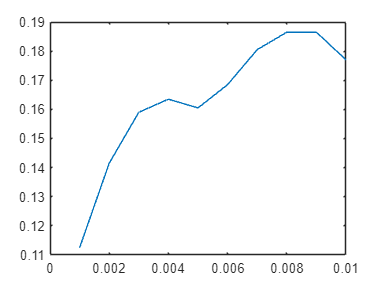

figure
plot(var_range,NARMSE_var_nomask)

save('NRMSE vs var no mask wireless','NARMSE_var_nomask','var_range')

%========================================

% {5.1} Single Dev Model

%========================================


%========================================
% {5.1.1} Single Dev Model for Response
%========================================

clc
clear
addpath("D:\matlab23a\bin\20240728-RC代码整理\public_func")
load("single_device_model_data.mat")

Input = readmatrix("20241219_wire_less_laser.txt");
Input_ex = 37 + Input*6;
gt_path = '20241219_wire_less_laser_gt.txt';
Label = readmatrix(gt_path);

ML = 4;
N = 14;
time_step = 0.2;

mask = zeros(14,ML);

for i = 1:14
t = dec2bin(i,4)';
t = string(t);
mask(i,:) = str2double(t)';
end
mask(mask == 0) = -1;

input_num = size(Input,1);


var_range = 0.001:0.001:0.01;

NARMSE_var = zeros(size(var_range));
ind_var = 1;
tic
for var = var_range

c_v_last = zeros(N,1);
curve_v = [];
mask_temp_last = [];

for i = 1:input_num
    for j = 1:ML
        mask_temp = mask(:,j);
        [a,b] = get_ab(Input_ex(i),mask_temp, ...
    p_fitresult_a,p_fitresult_b,n_fitresult_a,n_fitresult_b, ...
    nd_b_mean,pd_b_mean);
        if ~isempty(mask_temp_last)
            a_zeros_index = a == 0;
            change_polarity = (mask_temp - mask_temp_last)/2;
            change_index = change_polarity ~= 0;
            a(change_index&a_zeros_index) = change_polarity(change_index&a_zeros_index)/0.3;
        end
        a = var*randn(size(a)) + a;
        b = var*randn(size(b)) + b;
        result_fake = (a - c_v_last).*(1-exp(-time_step./b))+c_v_last;
        curve_v(:,ML*(i-1)+j) = result_fake;
        c_v_last = curve_v(:,ML*(i-1)+j);
        mask_temp_last = mask_temp;
    end
end


mask_num = N;

step = 1000;
Label_train = Label(1:step);
Label_test = Label(step+1:end);
ML = 4;


jj_range = -20:1:20;
fac_range = 1:20;
NR = zeros(size(fac_range,2),size(jj_range,2));
rowmin = min(curve_v,[],2);
rowmax = max(curve_v,[],2);

NR = search_para(fac_range,jj_range,step,ML,curve_v,rowmin,rowmax,Label,1);
[fac,jj] = plot_para(NR,fac_range,jj_range,curve_v, rowmin,rowmax,ML,step,Label,0,1);

jj_range = jj-2:0.1:jj+2;
fac_range = fac-2:0.1:fac+2;

NR = search_para(fac_range,jj_range,step,ML,curve_v,rowmin,rowmax,Label,1);
[fac,jj,NRMSE] = plot_para(NR,fac_range,jj_range,curve_v,rowmin,rowmax,ML,step,Label,0,1);
NARMSE_var(ind_var) = NRMSE;
disp(['====Var:',num2str(var),'Done...===='])
ind_var = ind_var + 1;
end

====Var:0.001Done...====
====Var:0.002Done...====
====Var:0.003Done...====
====Var:0.004Done...====
====Var:0.005Done...====
====Var:0.006Done...====
====Var:0.007Done...====
====Var:0.008Done...====
====Var:0.009Done...====
====Var:0.01Done...====


toc

历时 141.394306 秒。


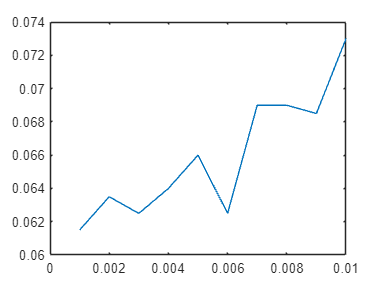

figure
plot(var_range,NARMSE_var)

save('NRMSE vs var with mask wireless','NARMSE_var','var_range')

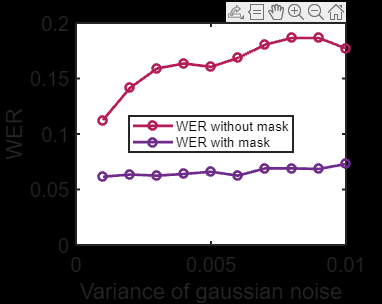

load("NRMSE vs var no mask wireless.mat")
% NARMSE_var_no_mask = NARMSE_var;
load("NRMSE vs var with mask wireless.mat")
NARMSE_var_with_mask = NARMSE_var;

figure
% 
% plot(var_range,NARMSE_var_nomask,'LineWidth',2)
% hold on
% plot(var_range,NARMSE_var_with_mask,'LineWidth',2)
% legend('NRMSE without mask','NRMSE with mask', ...
%     'Location','best', ...
%     'fontsize',10)
% figure_setting('NRMSE vs Variance',10,1.5,10)
% grid off
% xlabel('Variance of gaussian noise')
% ylabel('NRMSE')
plot(var_range,NARMSE_var_nomask,'LineWidth',2,'Marker','o','MarkerSize',6,'Color','#b61c57')
hold on
plot(var_range,NARMSE_var_with_mask,'LineWidth',2,'Marker','o','MarkerSize',6,'Color','#6e2b8c')
legend('WER without mask','WER with mask', ...
    'Location','best', ...
    'fontsize',10)
figure_setting('',15,1.5,15)
grid off
xlabel('Variance of gaussian noise')
ylabel('WER')
sc_size = get(0,'screensize');
set(gcf,'Position',[sc_size(1) sc_size(2) sc_size(3)*0.2 sc_size(4)*0.283 ...
    ])
ylim([0 0.2])
set(gca,'TickLength',[0.015 0.3])

% title('NRMSE vs Variance','FontSize',10,'FontName','Arial')
set(gcf,'color','none','InvertHardcopy','off');
print(gcf,'bar2 WER vs Mask length','-dmeta','-r600')

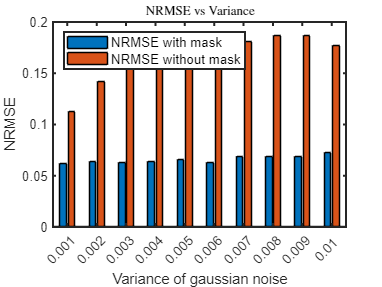



figure
bar([NARMSE_var_with_mask',NARMSE_var_nomask'])
xticklabels(mat2cell(var_range,1,10))
legend('NRMSE with mask','NRMSE without mask', ...
    'Location','northwest', ...
    'fontsize',10)
ylabel('NRMSE')
xlabel('Variance of gaussian noise')
figure_setting('NRMSE vs Variance',10,1.5,10)
grid off

function str = cell_trans(old)
    str = strrep(old,'_','.');
    str = str2double(str);
end

function [a,b] = get_ab(laser_current,mask_temp, ...
    p_fitresult_a,p_fitresult_b,n_fitresult_a,n_fitresult_b, ...
    nd_b_mean,pd_b_mean)

a = zeros(size(mask_temp));
b = ones(size(mask_temp));
p_index = mask_temp>0;
n_index = mask_temp<0;
b(p_index) = pd_b_mean;
b(n_index) = nd_b_mean;

    if laser_current <40
        % a = zeros(size(mask_temp));
    else
        a(p_index) = p_fitresult_a(laser_current*p_index(p_index));
        a(n_index) = n_fitresult_a(laser_current*n_index(n_index));
        b(p_index) = p_fitresult_b(laser_current*p_index(p_index));
        b(n_index) = n_fitresult_b(laser_current*n_index(n_index));
    end

end